Turbine Lab - Due 4/15/20

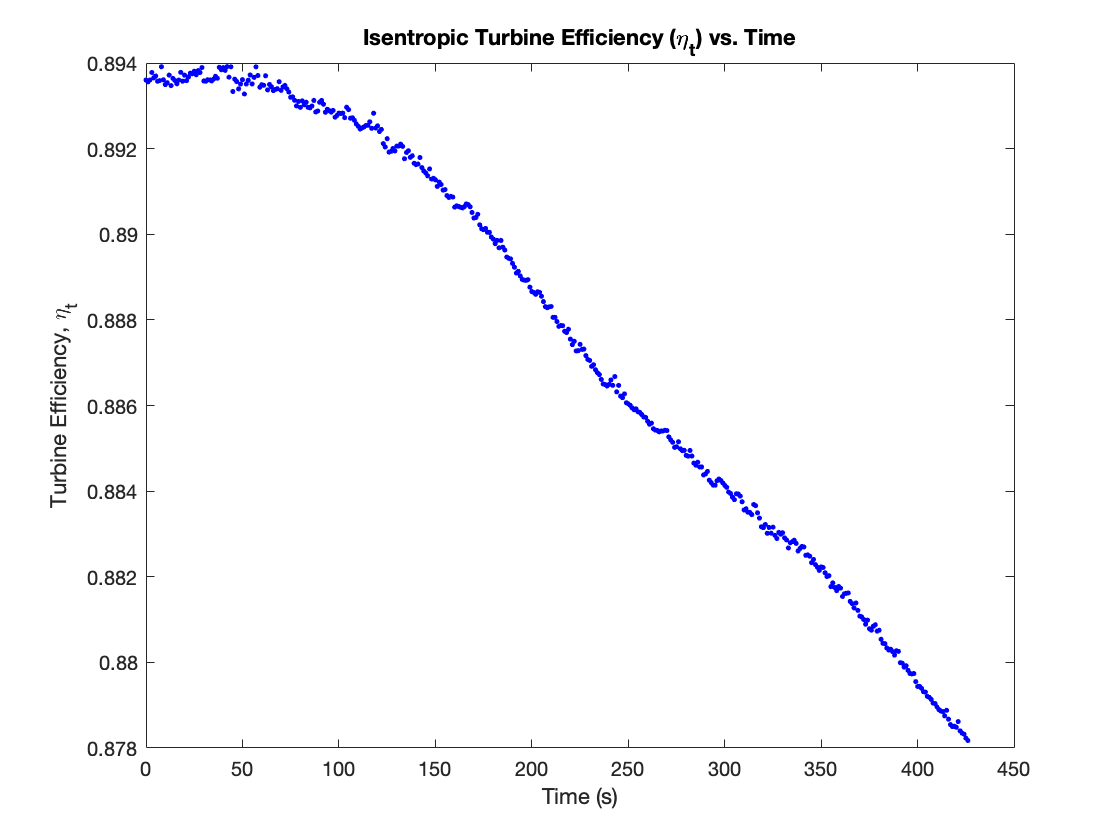

% Get the data
thermo = xlsread('thermo.xlsx');
[rNaN cNaN] = find(isnan(thermo));
thermo(rNaN,:) = [];

% Organize Data
time = thermo(:,1); % seconds
boiler_temp = thermo(:,2); % degrees C
turbine_in_temp = thermo(:,3); % degrees C
turbine_out_temp = thermo(:,4); % degrees C
boiler_press = thermo(:,5); % psig
turbine_in_press = thermo(:,6); % psig
turbine_out_press = thermo(:,7);
fuel_flow = thermo(:, 8); % L/min
generator = thermo(:, 9); % RPM
voltage = thermo(:, 10); % voltage
current = thermo(:, 11); % amperes
power = thermo(:,12); % watts
time = time - min(time); % adjusting time vector to start at zero
%b_temp_ave = mean(boiler_temp)
%bpminin = min(boiler_press) %*6.8948/100
%bpmaxin = max(boiler_press) %*6.8948/100
%themin_out = min(turbine_out_temp)
%themax_out = max(turbine_out_temp)
%%tpminout = min(turbine_out_press) %*6.8948/100
%tpmaxout = max(turbine_out_press) %*6.8948/100
%ave_turb_out_temp = mean(turbine_out_temp)
%turb_in_p_min = min(turbine_in_press) %*6.8948/100
%turb_in_p_max = max(turbine_in_press) %*6.8948/100
%turb_in_temp_ave = mean(turbine_in_temp)
%turb_out_temp_ave = mean(turbine_out_temp)
%total_time = max(time)

% Turbine Inlet Specific Enthalpy
t_in_h = zeros(1,length(turbine_in_press));
for i = 1:length(t_in_h)
    t_in_h(i) = linear_int(min(turbine_in_press), max(turbine_in_press), turbine_in_press(i), 2725.54, 2723.65);
    % units of kj/kg
end

% Boiler Specific Enthalpy
b_h = zeros(1,length(boiler_press));
for i = 1:length(b_h)
    b_h(i) = linear_int(min(boiler_press), 108.281, boiler_press(i), 2817.54, 2812.36);
end

% Turbine Outlet Specific Enthalpy
t_out_h = zeros(1,length(turbine_out_press));
for i = 1:length(t_out_h)
    t_out_h(i) = linear_int(min(turbine_out_press), 4.1620, turbine_out_press(i), 2698.58, 2697.86);
end

% Isentropic Efficiency
h3s = 2694.84; % kj/kg calculated from site, ave sp entropy of s2 then used mean temp of turb_out
Nt = zeros(1,length(t_out_h));
for i = 1:length(Nt)
    Nt(i) = (t_in_h(i) - t_out_h(i))./(t_in_h(i) - h3s);
end

% Plot Turbine Efficiency Over Time
figure
plot(time, Nt, 'b.')
title('Isentropic Turbine Efficiency (\eta_t) vs. Time')
xlabel('Time (s)')
ylabel('Turbine Efficiency, \eta_t')

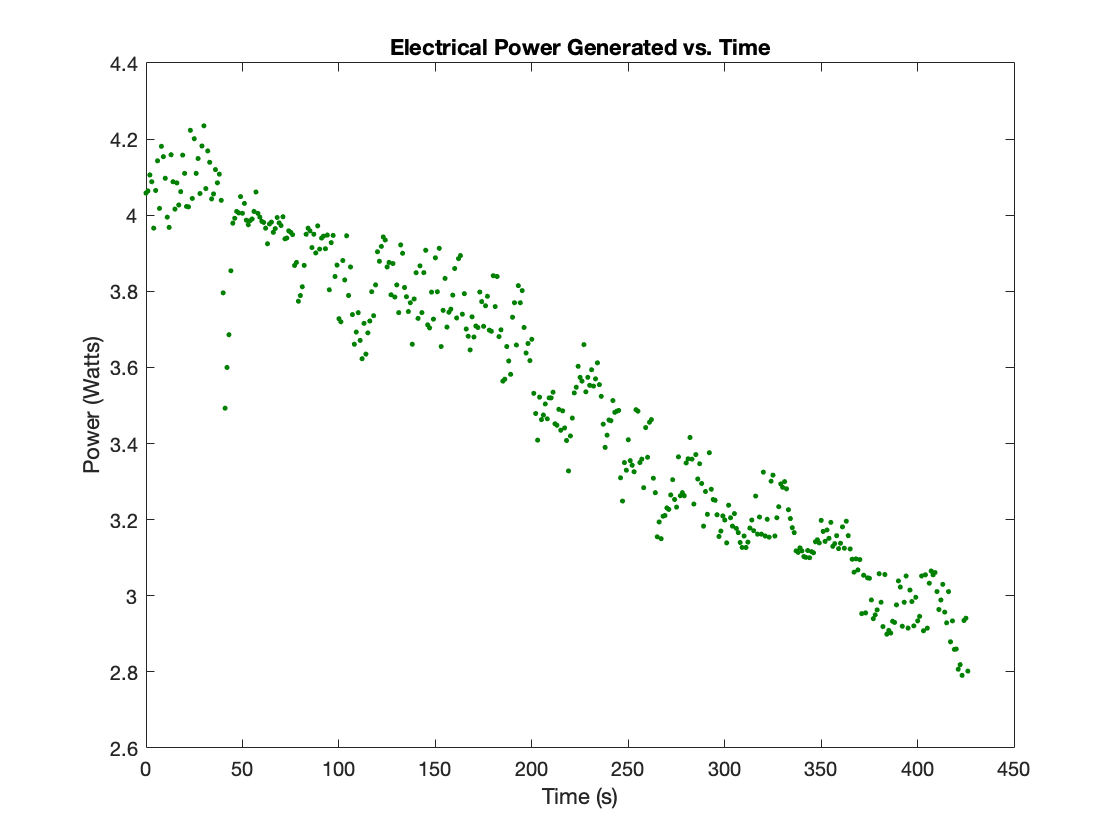

% Plot Power Generated Over Time
figure
plot(time, power, '.', 'color', [0 0.5 0])
title('Electrical Power Generated vs. Time')
xlabel('Time (s)')
ylabel('Power (Watts)')

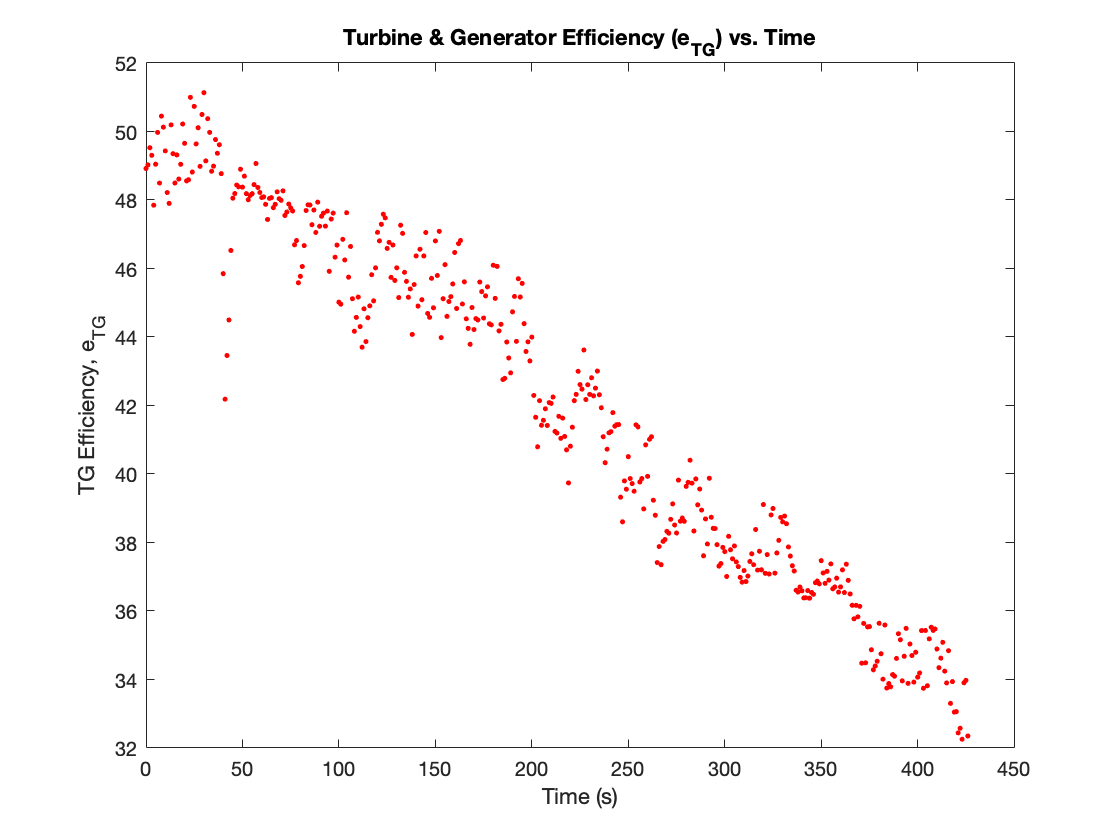


% Mass Flow Rate of Steam
m_dot_steam = 3.212538*(10^(-6)); % kg/s

% Efficiency of the Turbine & Generator
eTG = zeros(1, length(power));
for i = 1: length(eTG)
    eTG(i) = power(i)/(m_dot_steam * (t_in_h(i) - t_out_h(i)) * 1000);
end

% Plot efficiency of turbine and generator
figure
plot(time, eTG, 'r.')
title('Turbine & Generator Efficiency (e_T_G) vs. Time')
xlabel('Time (s)')
ylabel('TG Efficiency, e_T_G')

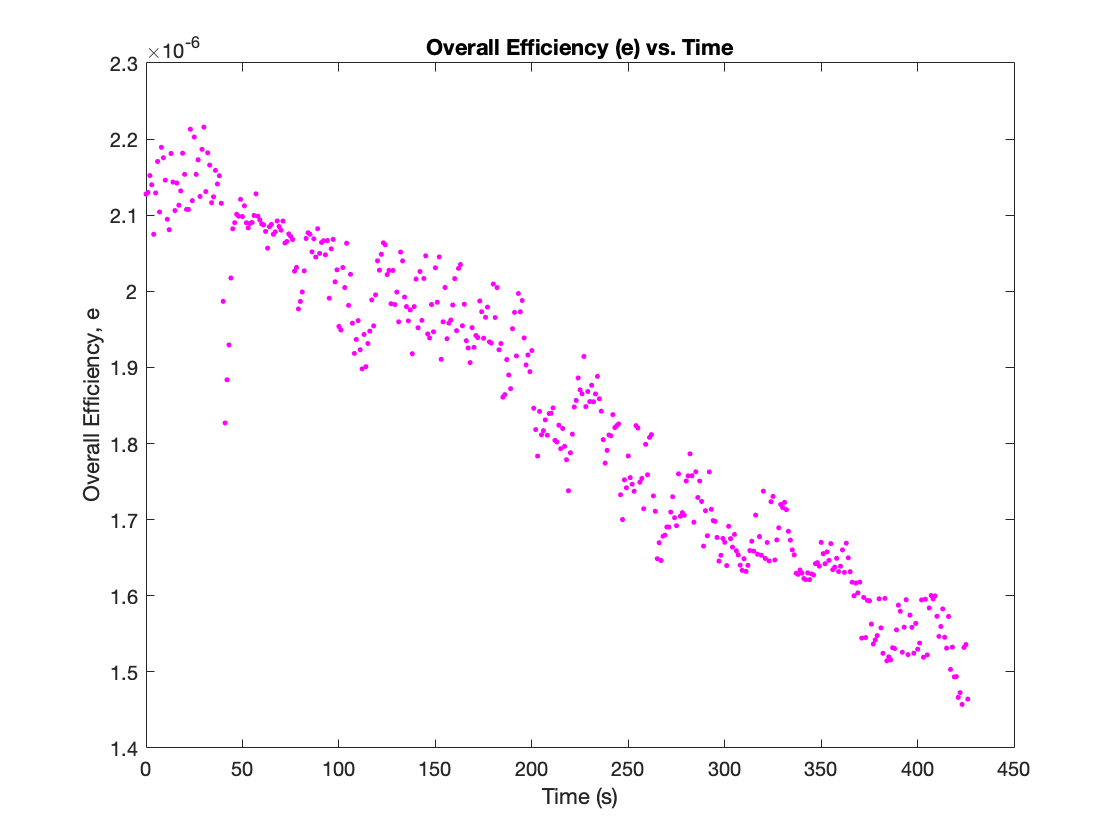


% Overall Efficiency
e = zeros(1,length(power));
denom = 381283.735;
for i = 1:length(e)
    e(i) = power(i)/(denom * fuel_flow(i)); 
end

% Plot Overall Efficiency Over Time
figure
plot(time, e, 'm.')
title('Overall Efficiency (e) vs. Time')
xlabel('Time (s)')
ylabel('Overall Efficiency, e')

% Answers to Questions
% Q1
Ave_h_1 = mean(b_h)

Ave_h_1 = 2.8143e+03

Ave_h_2 = mean(t_in_h)

Ave_h_2 = 2.7243e+03

nozzle_h_diff = mean(t_in_h)-mean(b_h)

nozzle_h_diff = -90.0054


% Q2
Ave_h_3 = mean(t_out_h)

Ave_h_3 = 2.6982e+03

h3s = 2694.84

h3s = 2.6948e+03

Ave_Nt = mean(Nt)

Ave_Nt = 0.8876


% Q3
Ave_eTG = mean(eTG)

Ave_eTG = 42.0403


% Q4
Ave_e = mean(e)

Ave_e = 1.8447e-06

%e
e(1)

ans = 2.1277e-06

function out = linear_int(A, B, C, D, E)
out = D+(E-D)*((C-A)/(B-A));
end